% Compressed Sensing Examples
% Copyright Brunton, Kutz, Proctor, 2016, All Rights Reserved
% Code by Steven L. Brunton (sbrunton@uw.edu)

clear; close all; clc

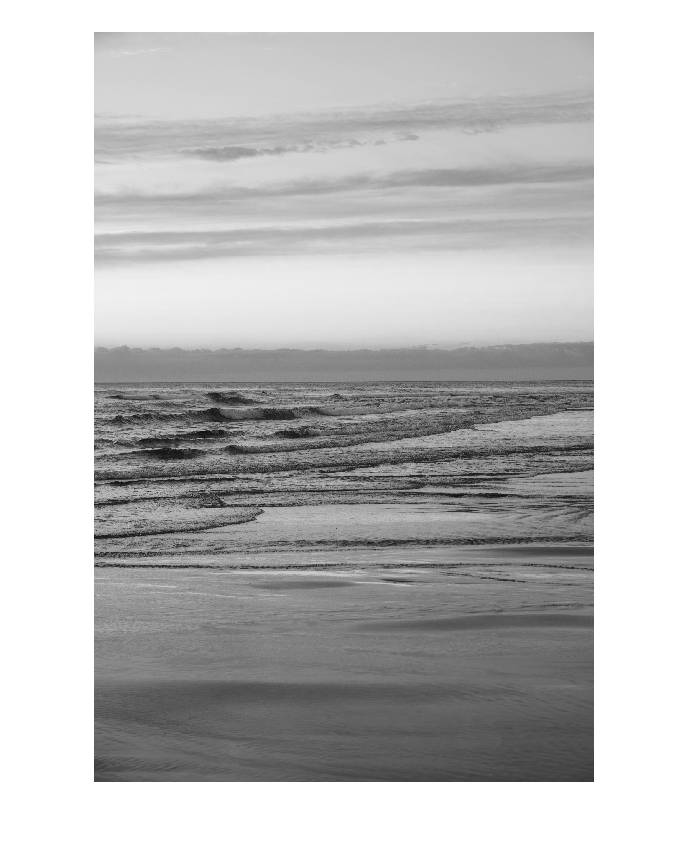

figure
A=imread('scene', 'jpeg'); % Load image
Abw=rgb2gray(A);           % Convert image to grayscale
imshow(Abw)               % Plot image

axis off
set(gcf,'PaperPositionMode','auto')
print('-depsc2', '-loose', '.\\figures\\f_chCS_ex01a');

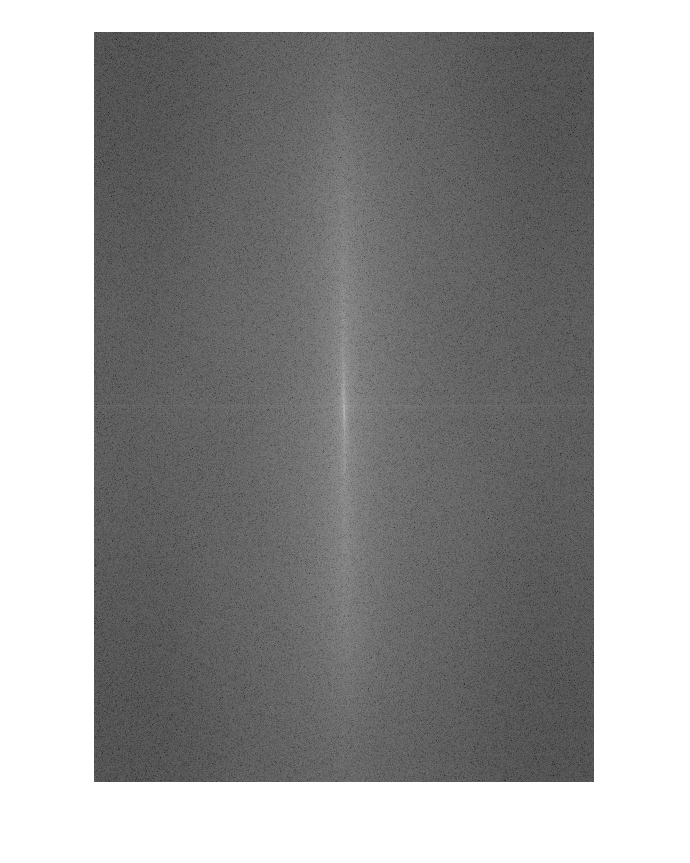


%% Compute the FFT of our image using fft2
At=fft2(Abw);
F = log(abs(fftshift(At))+1);  % put FFT on log-scale
imshow(mat2gray(F),[]);

axis off
set(gcf,'PaperPositionMode','auto')
print('-depsc2', '-loose', '.\\figures\\f_chCS_ex01b');

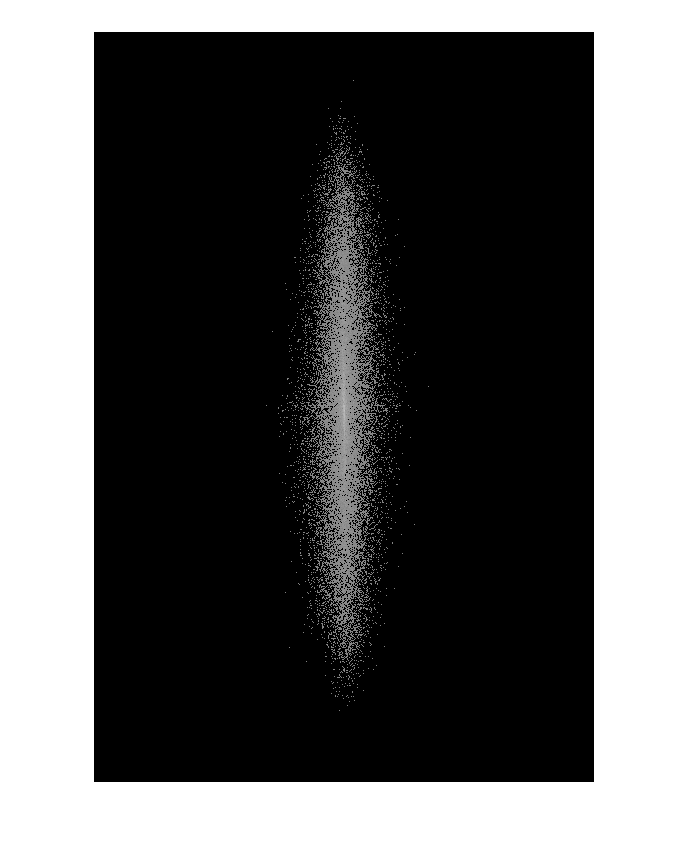


%% Zero out all small coefficients and inverse transform
Bt = sort(abs(At(:)));
keep = 0.05;
thresh = Bt(floor((1-keep)*length(Bt)));
ind = abs(At)>thresh;
Atlow = At.*ind;
Flow = log(abs(fftshift(Atlow))+1);  % put FFT on log-scale
imshow(mat2gray(Flow),[]);

axis off
set(gcf,'PaperPositionMode','auto')
print('-depsc2', '-loose', '.\\figures\\f_chCS_ex01c');

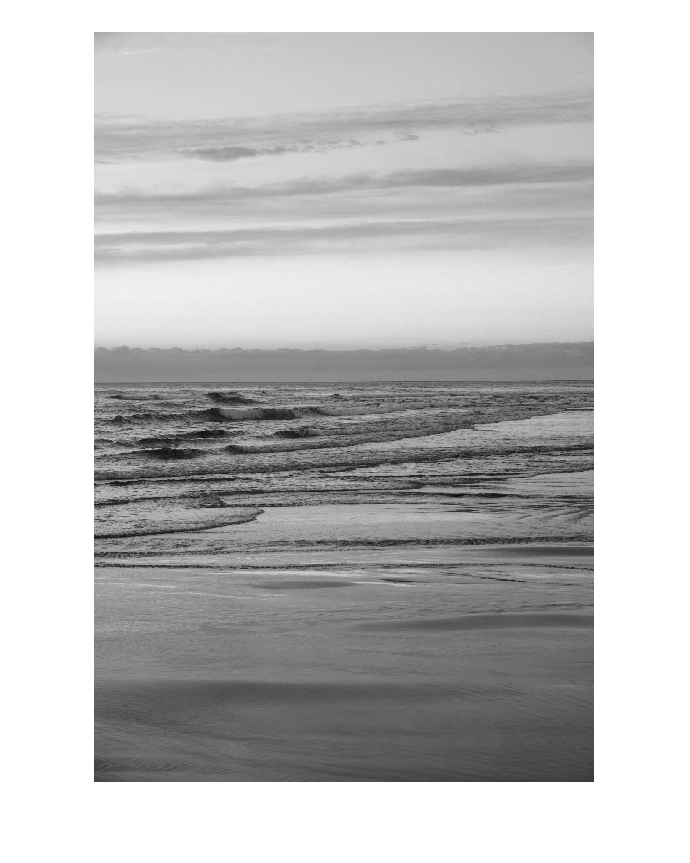


%% Plot Reconstruction
Alow=uint8(ifft2(Atlow));
imshow(Alow)

axis off
set(gcf,'PaperPositionMode','auto')
print('-depsc2', '-loose', '.\\figures\\f_chCS_ex01d');

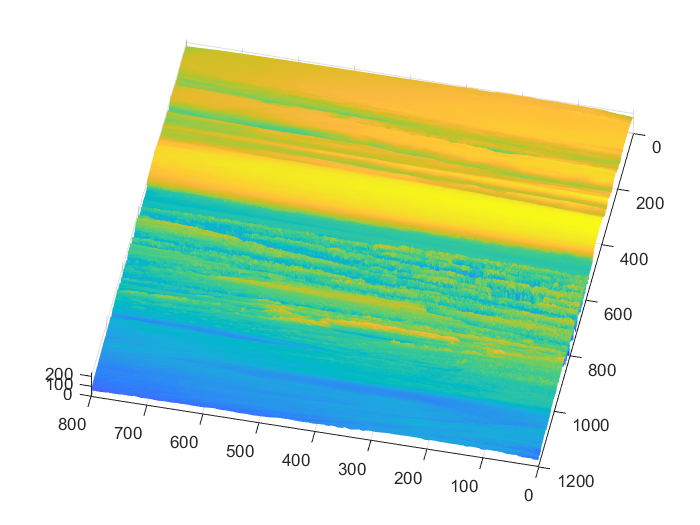


%%
figure
Anew = imresize(Abw,.2);
surf(double(Anew));
shading flat, view(-168,86)

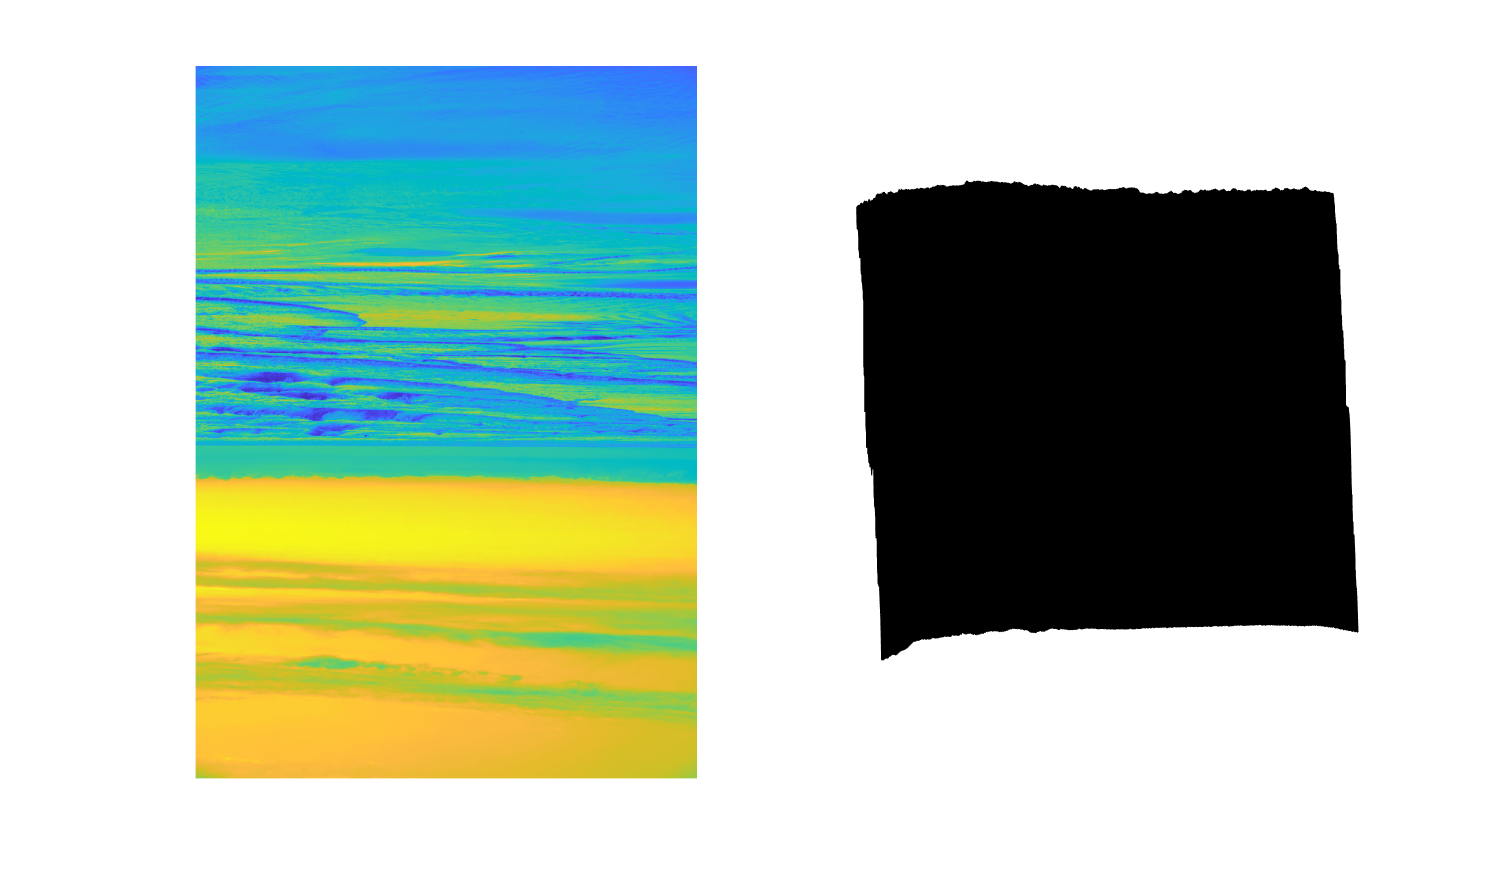



subplot(1,2,1)
surf(double(Anew));
shading flat, view(0,90)
axis off

subplot(1,2,2)
surf(double(Anew));
view(-3,72)
axis off

set(gcf,'Position',[10 10 1200 700])
set(gcf,'PaperPositionMode','auto')
print('-depsc2', '-loose', '.\\figures\\f_chCS_ex01e');